# Filter Comparisons

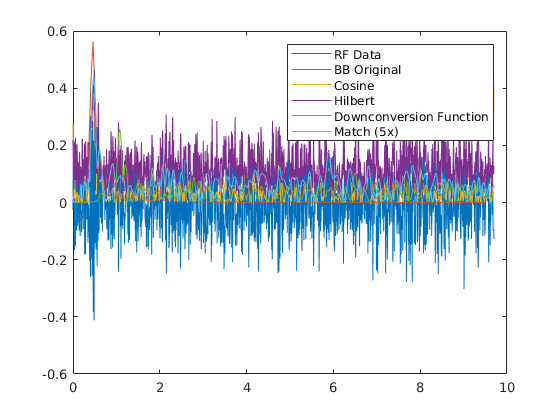

clear; clc;
addpath('../functions');

data = obtain_data(300,'rf',3);
x = linspace(0, 9.7, 1520);

plot(x, real(data));
hold on;

% Plot the original baseband
data_bb = obtain_data(300, 'bb', 3);
delay = 0.105;
x = linspace(0 + delay, 9.5, 186);
plot(x, abs(data_bb));

% Downconversion by multiplication of cosine
data_bb2 = cosine_filter(data, 3);
x = linspace(0, 9.7, 1520);
plot(x, abs(data_bb2));

% Downcoversion using hilbert transform
data_bb3 = hilbert_downconvert(data, 3);
x = linspace(0, 9.7, 1520);
plot(x, abs(data_bb3));

% Downconversion using downconversion function
data_bb4 = downconvert(data, 3);
x = linspace(0, 9.7, 1520/2);
plot(x, abs(data_bb4));

% Downconversion using matched filtering
s_tx = uwb_wavelet(23.3e9, 1.4e9, 7.29e9);
data_bb5 = matched(data, s_tx, 7.29e9);
x = linspace(0, 9.7, 1520);
plot(x, abs(data_bb5)/5);

legend('RF Data', 'BB Original', 'Cosine', 'Hilbert', 'Downconversion Function', 'Match (5x)');

hold off;

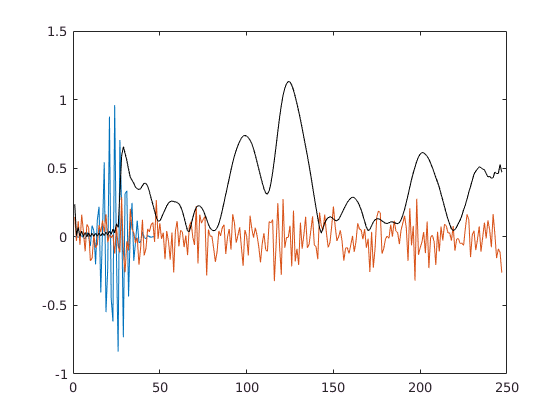

% Matched filter experiment
s_tx = uwb_wavelet(23.3e9, 1.4e9, 7.29e9);
s_rx = [zeros(1, 100), s_tx, zeros(1, 100)];
s_rx_noise = awgn(s_rx, 5)/5;

plot(s_tx);
hold on
plot(s_rx_noise)

s_rx_matched = matched(s_rx_noise, s_tx, 7.29e9);
plot(abs(s_rx_matched), 'Color', 'black');
hold off